# Chapiter 7 : Optimum filters

## EX 7.1: FIR Wiener - Filtering application (7.2.1)

In the filtering problem, a signal d[n], whose autocorrelation is known, is to be estimated from a noise corrupted observation : $x[n] = d[n] + v[n]$

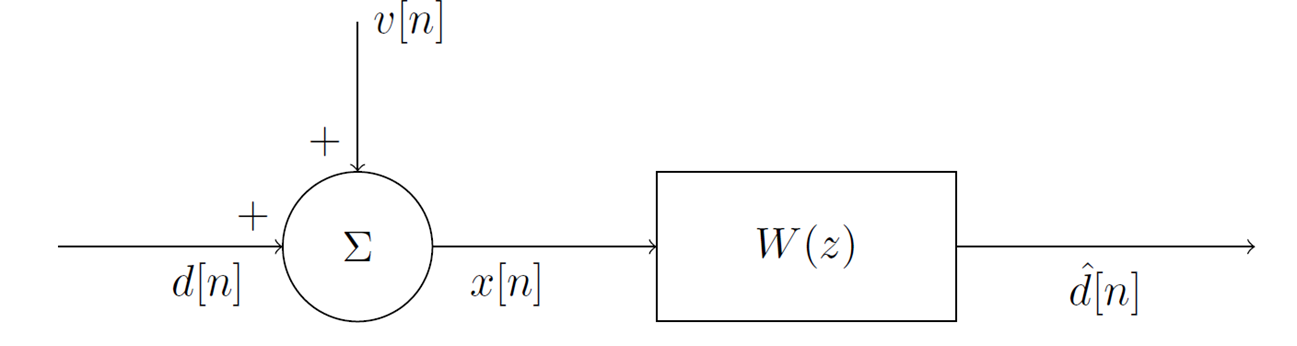

Let d[n] be an AR(1) process excited by a zero mean white noise with unit variance:

$d[n] = a[1]d[n - 1] + w[n]$          where a[1] = 0.8

and suppose that d[n] is observed in the presence of uncorrelated white noise v[n] with variance $\sigma_v^2$. The signal d[n] has a unit variance.

**The goal is to filter x[n] with Wiener filter W(z) to estimate d[n].**

clear; close all;
rng default;

## Signals creation

### Parameters

a1 = 0.8;
Alpha = 0.8;
SigmaW = 1;
SigmaV = 1;
N = 500;
p = 1;
NFFT = 1024;
param = table(a1, Alpha, SigmaW, SigmaV, N, p);
disp(param)

    a1     Alpha    SigmaW    SigmaV     N     p
    ___    _____    ______    ______    ___    _

    0.8     0.8       1         1       500    1



### Signal generation

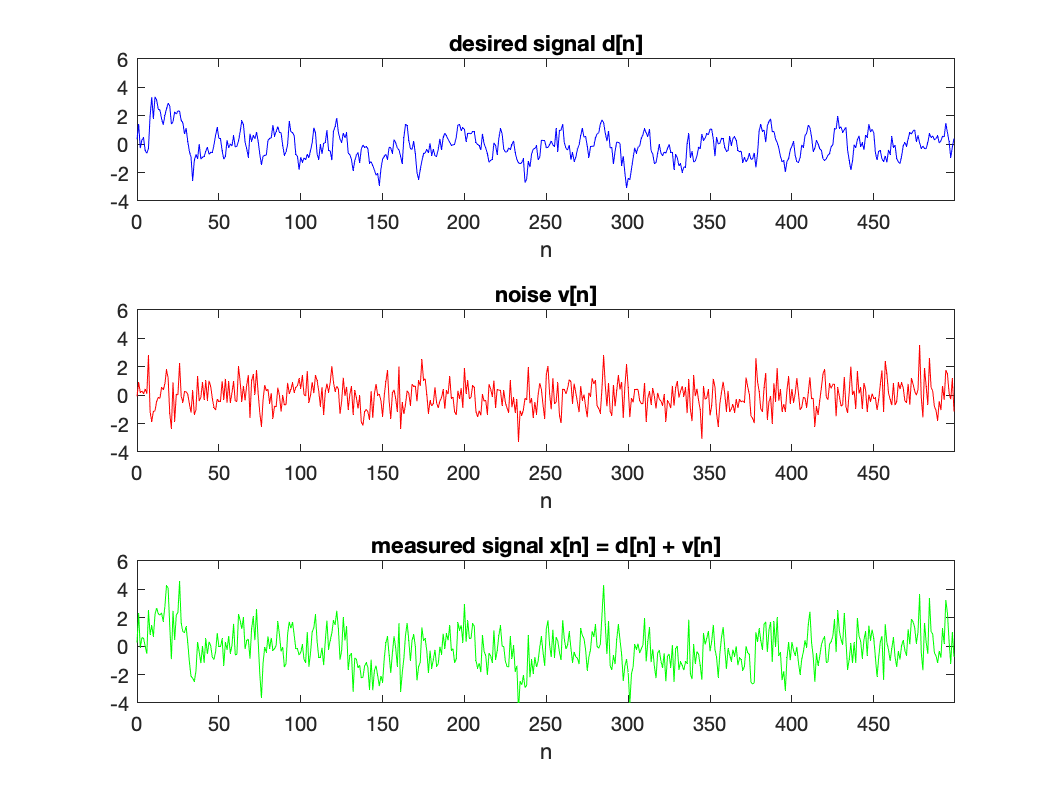

wn = SigmaW*randn(1,N);             % noise process
vn = SigmaV*randn(1,N);             % measurement noise
dn = a1*filter(1, [1, -Alpha], wn);
dn = dn/std(dn);                    % scale de dn
n = 0:N-1;

tiledlayout(3,1)
ax1 = nexttile;
    plot(n, dn, 'b')
    title('desired signal d[n]')
    xlabel('n')
ax2 = nexttile;
    plot(n, vn, 'r')
    title('noise v[n]')
    xlabel('n')
ax3 = nexttile;
    plot(n, dn+vn, 'g')
    title('measured signal x[n] = d[n] + v[n]')
    xlabel('n')
linkaxes([ax1,ax2,ax3], 'xy');
ax1.XLim=[0, N-1];
ax1.YLim=[-4, 6];

## Theoretical FIR wiener filter

### Design filter

By knowing the signal characteristics, the Wiener filter based on its theoretical statistical parameters can be designed:

By assuming that v[n] is zero-mean and not correlated with d[n], the Wiener-Hopf equation simplied to :


$$[R_{d} + R_{v}]w = r_{d}$$


- As the process d[n] is a AR(1) the theoretical auto-correlation of the desired signal is known.  For a first order Wiener filter (p=1), the theoretical autocorrelation matrix can be built:

$r_{d}[k] = \alpha^{k}$ with $\alpha = a[1] = 0.8$

         
$${\mathit{\mathbf{R}}}_d =\left\lbrack \begin{array}{cc}
r_d \left\lbrack 0\right\rbrack  & r_d \left\lbrack 1\right\rbrack \\
r_d \left\lbrack 1\right\rbrack  & r_d \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & \alpha \\
\alpha  & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & 0\ldotp 8\\
0\ldotp 8 & 1
\end{array}\right\rbrack$$



$${\mathit{\mathbf{r}}}_d =\left\lbrack \begin{array}{c}
r_d \left\lbrack 0\right\rbrack \\
r_d \left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
\alpha 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack$$
 

- As the noise as a unit variance, the theoretical autocorrelation of the noise is known:


$$r_{v}[k] = \sigma_v^2\delta[k] = \delta[k]$$



$$R_v =\left\lbrack \begin{array}{cc}
\sigma_v^2 \; & 0\\
0 & \sigma_v^2 \;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & 0\\
0 & 1
\end{array}\right\rbrack$$


- It gives the theoretical Wiener-Hopf equation


$$\left\lbrack \left\lbrack \begin{array}{cc}
1\; & \alpha \\
\alpha  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\sigma_v^2 \; & 0\\
0 & \sigma_v^2 \;
\end{array}\right\rbrack \right\rbrack \left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
\alpha 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cc}
2\; & 0\ldotp 8\\
0\ldotp 8 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack$$


- By solving that Wiener-Hopf equation, the Wiener coefficient can be estimated:


$$\left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
2\; & 0\ldotp 8\\
0\ldotp 8 & 2
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 4048\\
0\ldotp 2381
\end{array}\right\rbrack$$


- The theoretical squared norm minimum error can be determined:


$$\xi_{\min } =r_d \left\lbrack 0\right\rbrack -w\left\lbrack 0\right\rbrack r_d \left\lbrack 0\right\rbrack -w\left\lbrack 1\right\rbrack r_d \left\lbrack 1\right\rbrack =0\ldotp 4048$$


The computed values are:

rd = a1.^[0:p]';
Rd = [rd, flip(rd)];
Rv = SigmaV^2 .* eye(2);
Rx = Rd + Rv;
W = inv(Rx)*rd;
E = rd(1) - rd'*W;

### Filter analysis

The frequency response and the zero and pole of the filter can be displayed. It creates a low pass filter.

W = tf(W',[1, zeros(1,p)],1);

### Signal filtering

The signal can now be filtered by the Wiener filter.

dhat = filter(cell2mat(W.Numerator), cell2mat(W.Denominator), xn);


### Signal noise ratio

The SNR can be then determined before and after filtering.

**Prior to filtering**, since $r_d \left\lbrack 0\right\rbrack =\sigma_d^2 =1$ and $r_v \left\lbrack 0\right\rbrack =\sigma_v^2 =1$, then the power in d[n] is equal to the power in v[n], $E\left\lbrace {\left|d\left\lbrack n\right\rbrack \right|}^2 \right\rbrace =E\left\lbrace {\left|v\left\lbrack n\right\rbrack \right|}^2 \right\rbrace =1$, and the signal to noise ratio is:

$\textrm{SNR}=10\textrm{log10}\left(\frac{E\left\lbrace {\left|d\left\lbrack n\right\rbrack \right|}^2 \right\rbrace }{E\left\lbrace {\left|v\left\lbrack n\right\rbrack \right|}^2 \right\rbrace }\right)=0$ dB

**After filtering**, the power in the signal can be estimated as follow:


$$E\left\lbrace {\left|d^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace ={\mathit{\mathbf{w}}}^T {\mathit{\mathbf{R}}}_d \mathit{\mathbf{w}}$$



$$E\left\lbrace {\left|v^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace ={\mathit{\mathbf{w}}}^T {\mathit{\mathbf{R}}}_v \mathit{\mathbf{w}}$$


$\textrm{SNR}=10\textrm{log10}\left(\frac{E\left\lbrace {\left|d^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace }{E\left\lbrace {\left|v^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace }\right)=2\ldotp 3$ dB

Then the Wiener filter increases the SNR by more than 2dB.

## Estimated Wiener filter

### Estimated autocorrelation

The previous part was using the theoretical autocorrelation of the desired signal and of the noise. In practice, most of the time this has to be estimated from the signal.

### Wiener filter design

By using the estimated autocorrelation, the wiener filter can be designed using the same calculation than before.

On low order filter, the estimation and the theoretical gives very similar result. This is because the estimated autocorrelation is very close to the theoretical. The difference will increase with high filter order (p>1).

% [w, E] = WienerFIR(x,d,p); % filter based on data
% Wcomp=[wTheo,w];
% figure;
% X = 1:p+1;
% bar(X,Wcomp);
% title('Wiener )

### Filter analysis

The frequency response and the zero and pole of the filter can be displayed. It creates a low pass filter.

### Signal filtering

The signal can now be filtered by the Wiener filter.

## Multi P

Let's observe the SNR if we increase the filter order.

Because of the non-linear phase of the Wiener FIR filter, the error signal can not be computed as **d-y. **There is a synchronisation problem. The SNR gain can not be computed as $10\textrm{log10}\left(\frac{\|\mathit{\mathbf{d}}\|}{\|\mathit{\mathbf{d}}-\mathit{\mathbf{y}}\|}\right)$. When p increases, the SNR gain increases but $10\textrm{log10}\left(\frac{\|\mathit{\mathbf{d}}\|}{\|\mathit{\mathbf{d}}-\mathit{\mathbf{y}}\|}\right)$increases and then decreases ! Do not use it !